1) We start by solving the equations for $\delta\dot{x}$ and $\delta\dot{y}$. We know that

$m\dot{v_x} = m\frac{dv_x}{dt} = -\frac{1}{2}C_xAv_x^2+u_x$.

We know that at equilibrium, $v_{x_e} = 100$ and $\frac{dv_x}{d_t}|_{v_x=v_{x_e}} = 0$. Thus, we can solve a system of equations for $u_{x_e}$ in terms of the constants in the original equation.


$$\frac{-1}{2m}C_xA(100)^2 + \frac{1}{m}u_{x_e} = 0$$



$$u_{x_e} = 500C_xA$$


Thus, we can write

$\delta\dot{v_x} = -\frac{1}{m}100C_xA\delta v_x+\frac{1}{m}\delta u_x$.

By symmetry,

$\delta\dot{v_y} = -\frac{1}{m}100C_xA\delta v_y+\frac{1}{m}\delta u_y$.

We now want to include the fact that $z = y-x$ into our equations. We can use the fact that z is linear to say that

$\delta\dot{z} = \delta\dot{y} - \delta\dot{x}$ and $\delta\dot{v_z} = \delta\dot{v_y} - \delta\dot{v_x}$

We ALSO know that $\delta v_y  = v_y - v_{y_e}$ and $\delta v_x = v_x - v_{x_e}$. Subtracting these two gives $\delta v_y - \delta v_x = v_y - v_x$ since $v_{y_e} = v_{x_e}$. By same logic, $\delta u_y - \delta u_x = u_y - u_x$. 

Putting this in the subtraction of our two previous equations, we get that

$\delta\dot{v_z} = -\frac{1}{m}100C_xA[v_y - v_x] + \frac{1}{m}[u_y-u_x]$.

2) The last equation after including the new variables they give in the problem becomes

$\delta\dot{v_z} = -\frac{1}{m}100C_xAv_z + \frac{1}{m}u_z$.

Taking the Laplace transform of both sides, and using the fact that the derivative of $z$ position is $v_z$, we see that


$$s^2 Z(s) = -\frac{1}{m}100C_xAsZ(s)+\frac{1}{m}U(s)$$



$$Z(s)[s^2 + \frac{1}{m}100C_xAs] = \frac{1}{m}U(s)$$



$$\frac{Z(s)}{U(s)} =G(S) =  \frac{1}{ms^2 + 100CxAs} = \frac{1}{s(ms + 100CxA)}$$


3) If we want to use an proportional controller, $K_p$ to stabilize $G$, our transfer function becomes 

$\frac{K_pG}{1 + K_pG}$.

We can rewrite this as

$\frac{K_p}{\frac{1}{G} + K_p}$.

Plugging our equation for G into this equation, we end up with the final function


$$\frac{K_p}{s(ms + 100C_xA) + K_p} $$$


which can be rewritten as $\frac{K_p/m}{s^2+100C_xA/m\cdot s+K_p/m}$. Now that it is in this form, we can use the Routh Criterion Test in order to see what values of $K_p$ allow for this transfer function to be stable.

$s^2$:               1                   $K_p/m$

$s^1$:         $\frac{100C_xA}{m}$                  0

$s^0$:             $\frac{K_p}{m}$    

Since $C_x > 0$ and $A > 0$ and $m > 0$, the first term of the second row is always positive. Thus, for this to be stable, the first term of the third row must always be positive. Hence, we can deduce that $K_p > 0$.

4) Plugging in $m$ = 2000kg, $C_x$ = 0.35, and $A$ = 2m^2, our function G becomes


$$G = \frac{1}{s(2000s + 100 * 0.35 * 2)} = \frac{1}{2000s^2 + 70s}$$


Now, our goal in this part of the problem is trying to fit a settling time of no more than 3 seconds, and an overshoot of no more than 20%. As the proportional controller is easiest to deal with, we try to use only this to solve the problem:

Using the equatoin from the previous problem, we plug in our new parameters to get a transfer function of

$\frac{K_p/m}{s^2+100C_xA/m\cdot s+K_p/m} = \frac{0.0005K_p}{s^2 + 0.035s + 0.0005K_p}$.

Now, we test this for different values of $K_p$ in order to figure out if we can keep

$t_s \le 3$ and $M_p \le 20\%$.

s = tf('s');
Kp = [0.1, 0.5, 1, 5, 10];
for kp = Kp
    sys = 0.0005 * kp / (s^2 + 0.035 * s + 0.0005 * kp);
    si = stepinfo(sys);
    st = si.SettlingTime;
    os = si.Overshoot;
    fprintf('Kp=%.1f has t_s %.4f and M_p %.4f\n', kp, st, os);
end

Kp=0.1 has t_s 2652.2365 and M_p 0.0000
Kp=0.5 has t_s 442.2346 and M_p 0.0000
Kp=1.0 has t_s 162.0847 and M_p 1.9258
Kp=5.0 has t_s 219.6279 and M_p 30.8541
Kp=10.0 has t_s 199.8564 and M_p 44.6799


We see that the value of $M_p$ is pretty good for smaller values of $K_p$. However, the value of $t_s$ seems to be smallest around $K_p = 1$ and even then it isn't small enough. We therefore will put an ADDITIONAL derivative controller to make the settling time smaller.

Letting the controller $K$ be equal to $K_p + K_d s$, our transfer function now becomes

$\frac{0.0005 * (K_ds + K_p)}{s^2 + (0.035 + 0.0005K_d)s + 0.0005K_p}$.

Checking for stability again, our Routh-Criterion Test looks like

$s^2$:                   1                        $K_p/m$

$s^1$:         $\frac{100C_xA + K_d}{m}$                  0

$s^0$:                  $\frac{K_p}{m}$    

The only difference here is the middle term which must be positive because $K_p$ is positive. Therefore, plugging in the values of $C_x$ and $A$ and $m$ we see that $K_d > -70$.

To find the values of $K_p$ and $K_d$ we try out a few values of each.

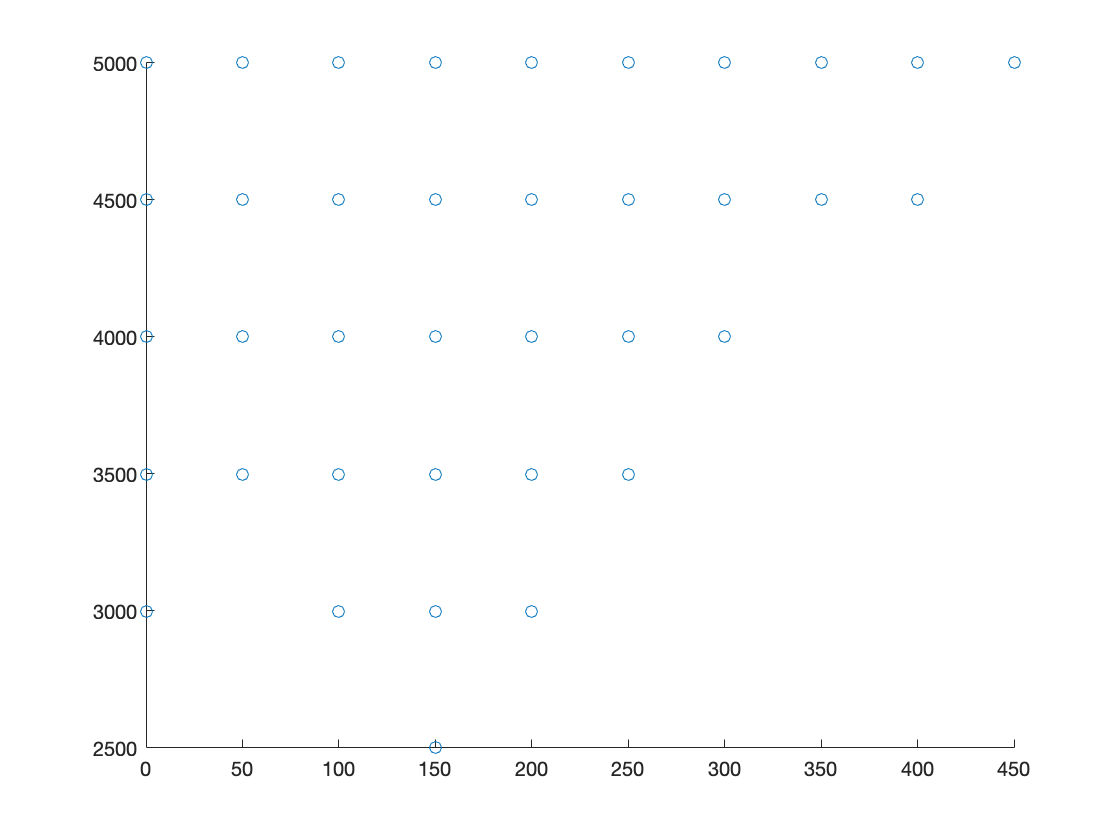

s = tf('s');
Kp = 0:50:500;
Kd = 0:500:5000;
xval = [];
yval = [];
for kp = Kp
    for kd = Kd
        sys = 0.0005*(kd*s+kp)/(s^2+(0.035+0.0005*kd)*s+0.0005*kp);
        ts = stepinfo(sys).SettlingTime;
        mp = stepinfo(sys).Overshoot;
        if ts <= 3 && mp <= 20
            xval = [xval kp];
            yval = [yval kd];
        end
    end
end
scatter(xval, yval);

The points that you see plotted are the values of $(K_p, K_d)$ that satisfy the constraints. We see that higher values of $K_p$ and $K_d$ work, and have better results. Let us choose $K_p = 35000
$ and $K_d = 18000$ just out of randomness.

kp = 35000;
kd = 18000;
sys = 0.0005*(kd*s+kp)/(s^2+(0.035+0.0005*kd)*s+0.0005*kp);
ts = stepinfo(sys).SettlingTime;
mp = stepinfo(sys).Overshoot;
fprintf('(Kp, Kd) = (%d, %d) has t_s %.4f and M_p %.4f.\n',kp,kd,ts,mp);

(Kp, Kd) = (35000, 18000) has t_s 1.3088 and M_p 11.9728.


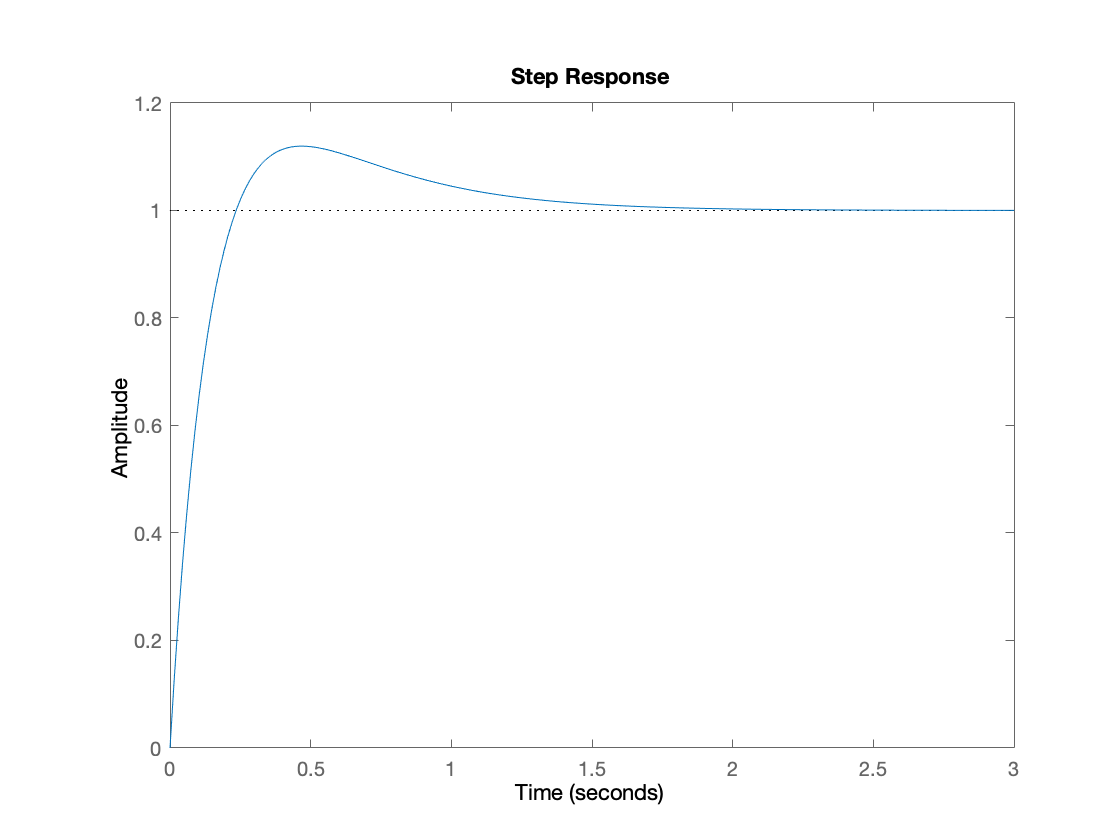

step(sys);

Below is a screenshot of the Simulink Diagram and the Scope Output.

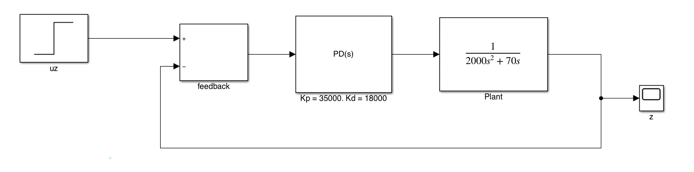

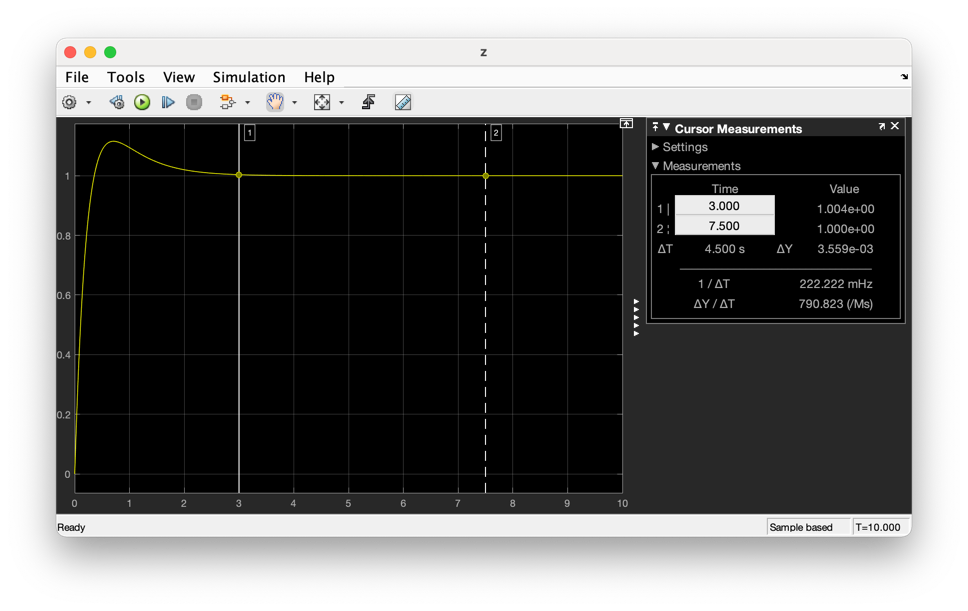

5)

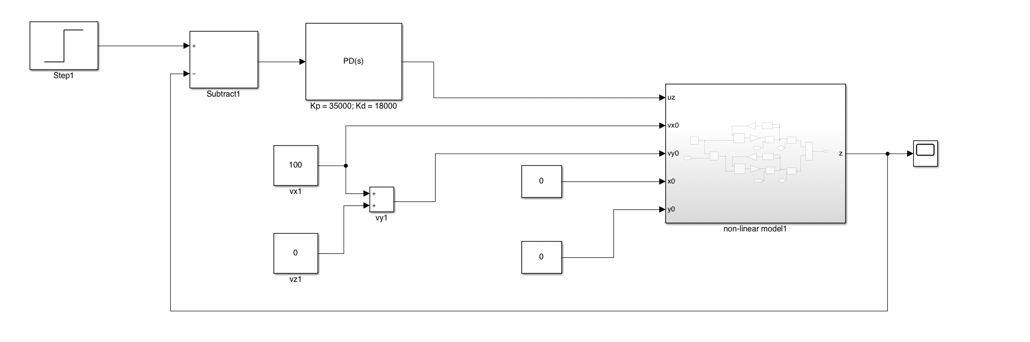

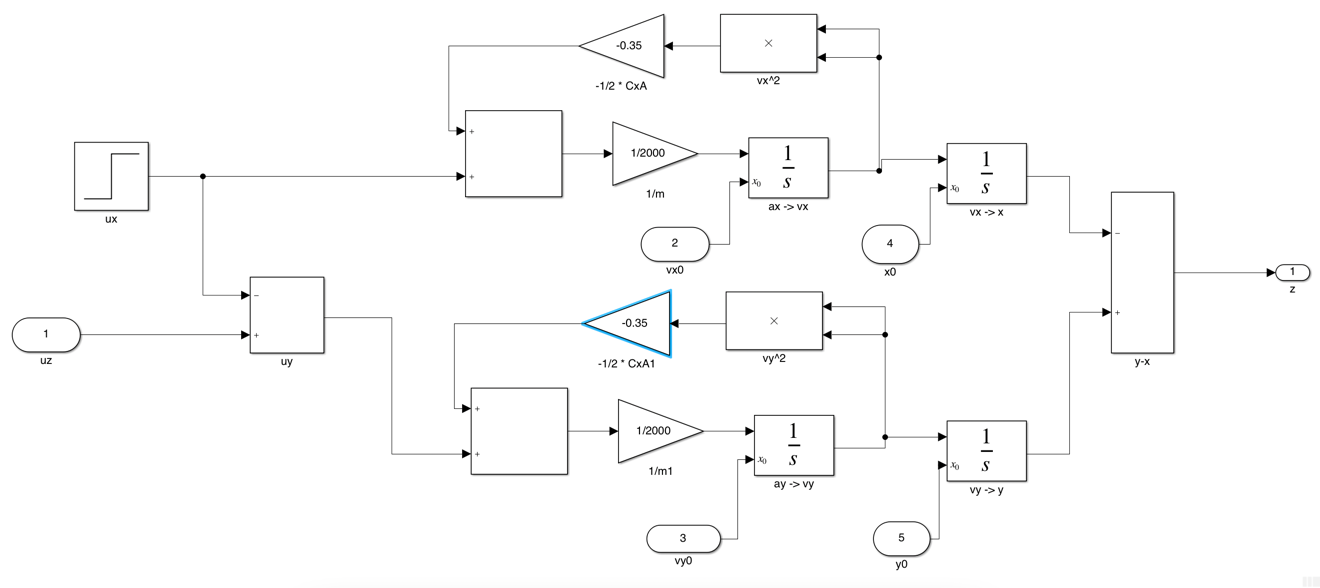

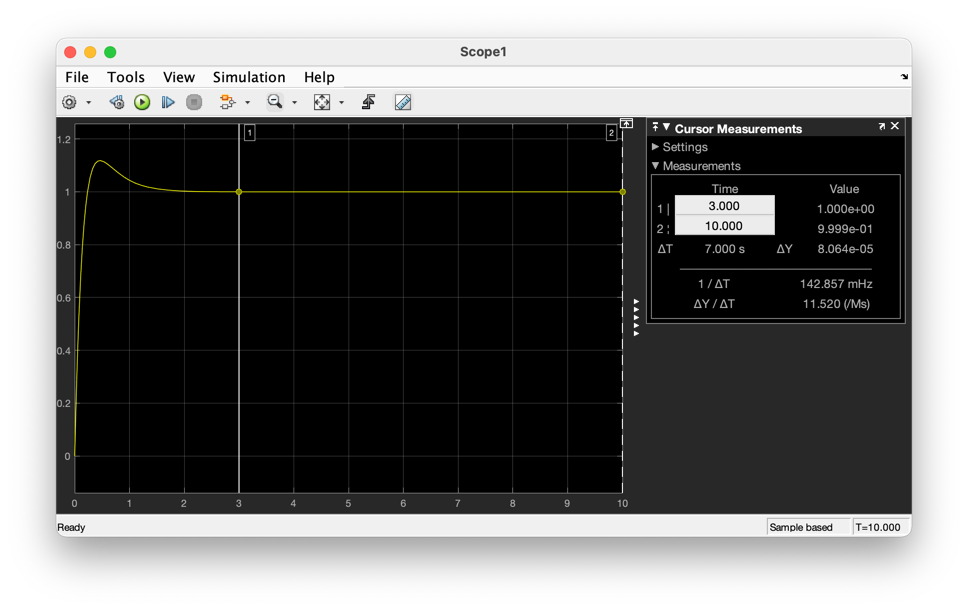

The above is for an input of $v_{x_0} = 100$ and $v_{y_0} = 100$ and $x_0 = y_0 = 0$. Even though $x_0$ should not equal $y_0$ in real life (cars on top of each other), I decided to test it here just to see how the car in front would be able to manage the control. I will test more plausible values of $z_0$ in the coming paragraphs. We see that the graph is very similar to our original linear one we did in problem 4. This does seem to satisfy the constraints given in the problem. Now, we proceed to test different input initial velocities to see the range in which our system holds.

The first thing I noticed after trying out different starting values for $v_x$ and $v_y$ is that if they were different AND the positions were the same, the constraints were almost instantly violated. My control loop seems to work with very minute differences such as $100.0$ and $101$ but if they are more different the overshoot is very large. This is because it is pretty hard to control two cars that start from the exact same spot. Here is an example with $v_x = 100.0$ and $v_y = 101

$ as starting conditions.

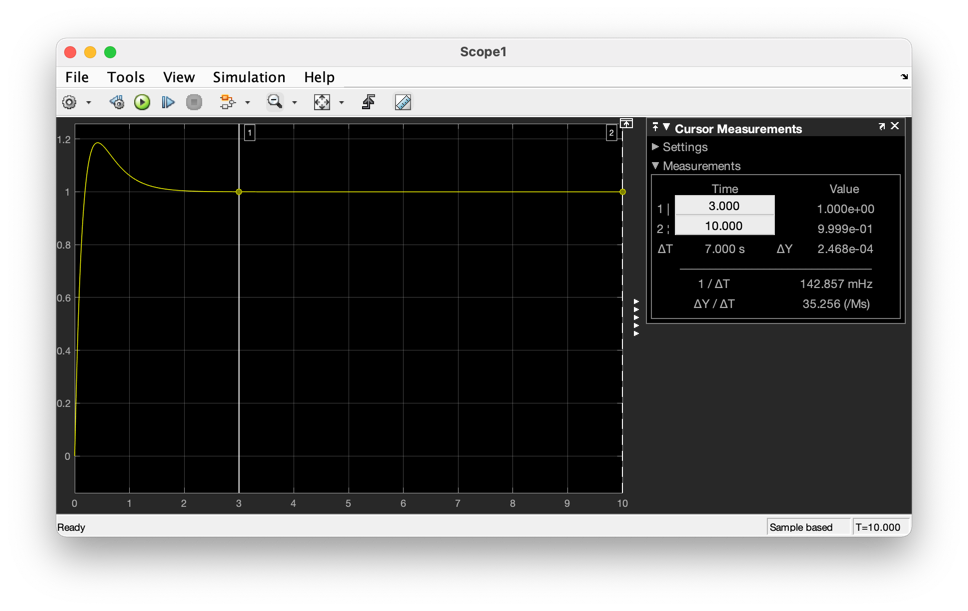

In fact, when $z_0 = y_0 - x_0 = 0$, the range of $v_{y_0}-v_{x_0}$ that works is about $-0.94$ to $1.00$. This basically means if we keep $v_{x_0} = 100$, $v_{y_0}$ can be from $99.06$ to $101$. This was what I found by testing and retesting values many many many times.

Notice that if we set the initial distances for the cars farther apart, we can get bigger differences in $v_{x_0}$ and $v_{y_0}$. Let us start the cars 2 units apart aka $x_0 = 0
$ and $y_0 = 2$. For the following, we will test $v_{x_0} = 100$ and $v_{y_0} = 108$. It still satisfies the constraints! In fact, the range for the difference in velocities is about $-9.1$to $9.2$.

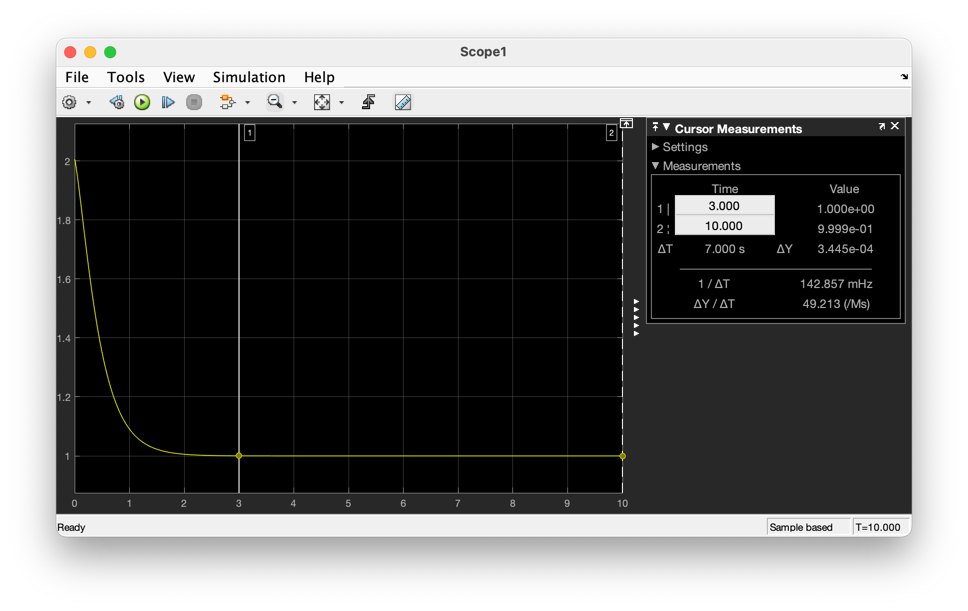

Now, if we test a larger distance like $y_0 - x_0 = 5$ we get that the maximum velocity difference can be up to 35!!! The range is from about $-30$ to $35$.

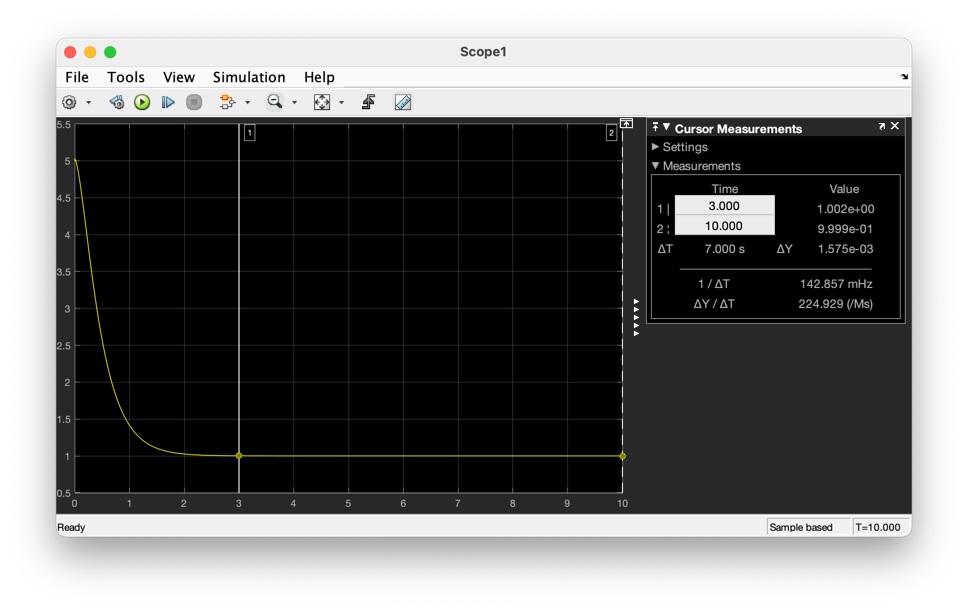

This is really amazing and it showcases how the farther apart cars are the more they are able to keep in control and maintain good overshoot and settling time, which is the goal of the problem.

6) We try this again with the new values of $A = 1.5$ and $C_x = 0.3$. We replot the nonlinear Simulink Scope: (Note: the only things we have to change are the Gain blocks in our non-linear model diagram that include $C_xA%$ and such.

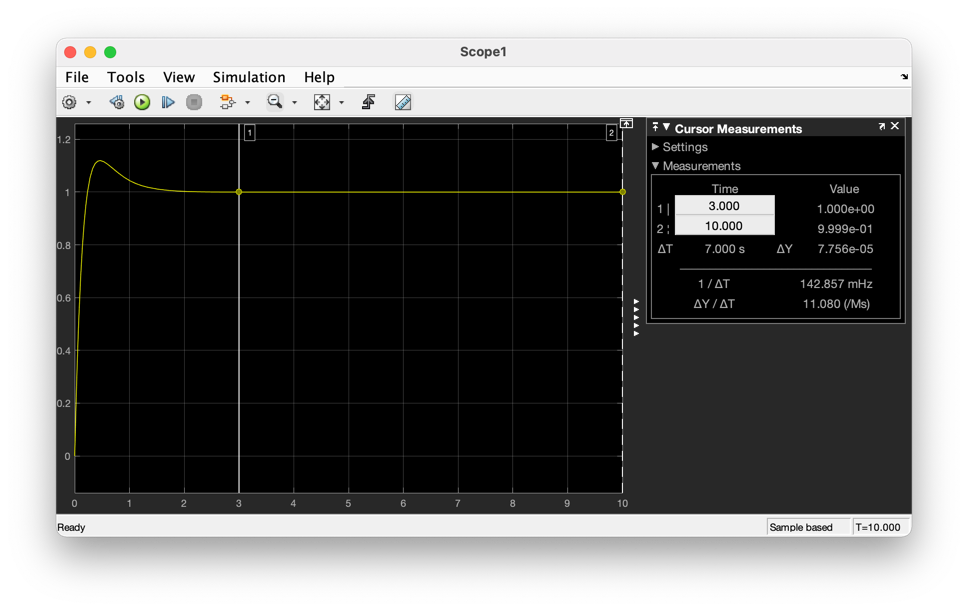

We see that it still satisfys the requirements. The overshoot as you can see in the above diagram is under 1.2, the allowed amount. The settling time is still very good. In this part of the problem, I will only test for $y_0 - x_0 = 0$ and find the max velocity difference because results are very similar to part 5.

The following is for $v_x = 100.0$ and $v_y = 101

$. And it still works! But very barely and any higher value is likely to fail the overshoot condition.

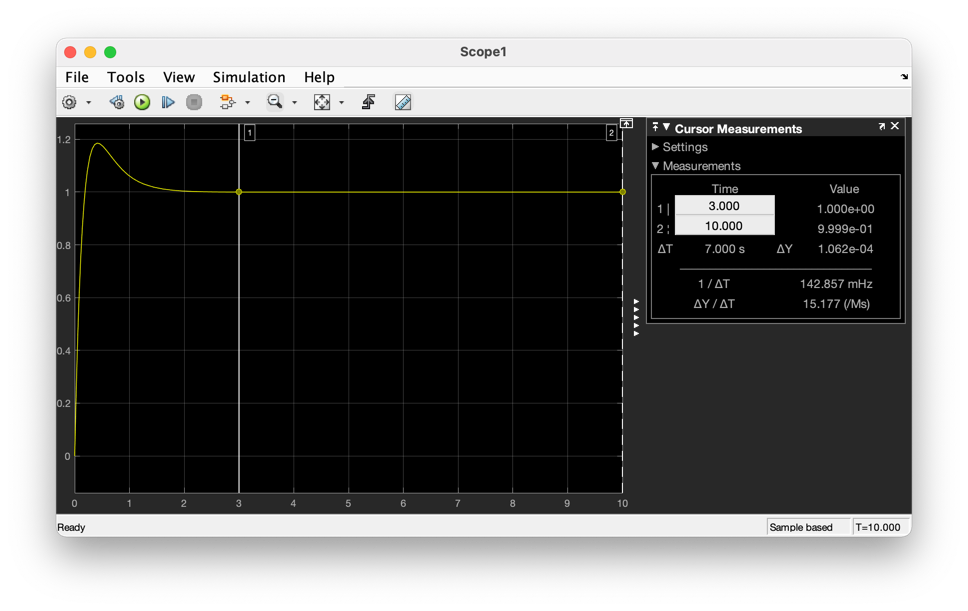

This is my new model: just for reference, I only changed the gains:

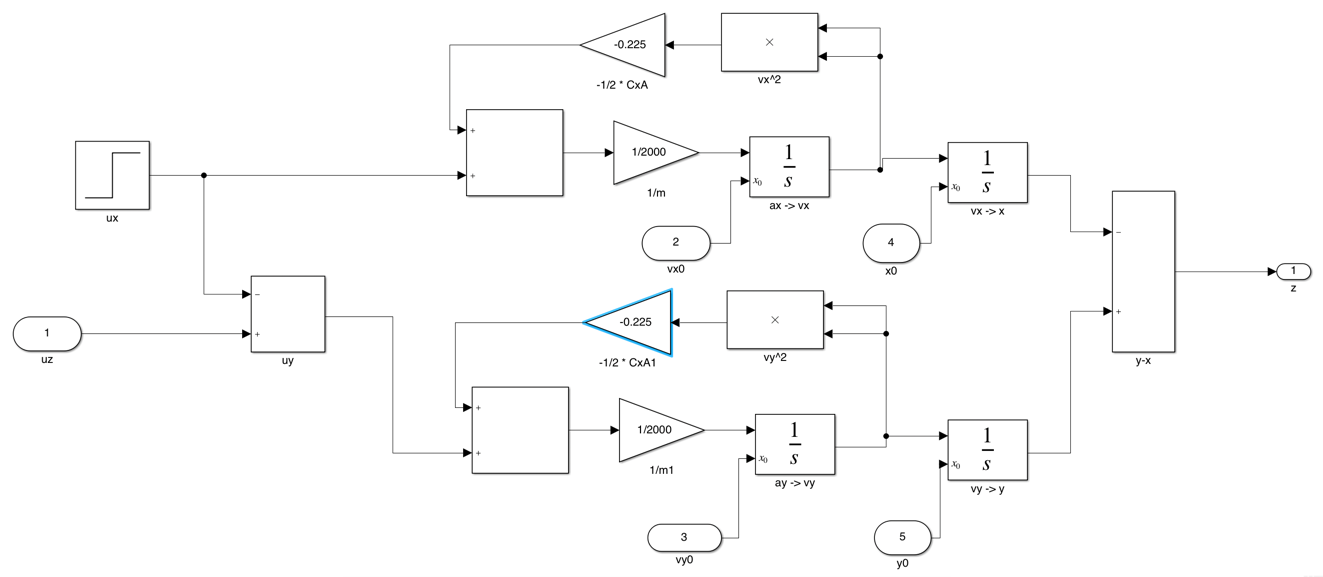

7) Here, we add a wind force of 500 Newtons to the sum of the forces (before dividing by mass to get acceleration) only for the x-car.

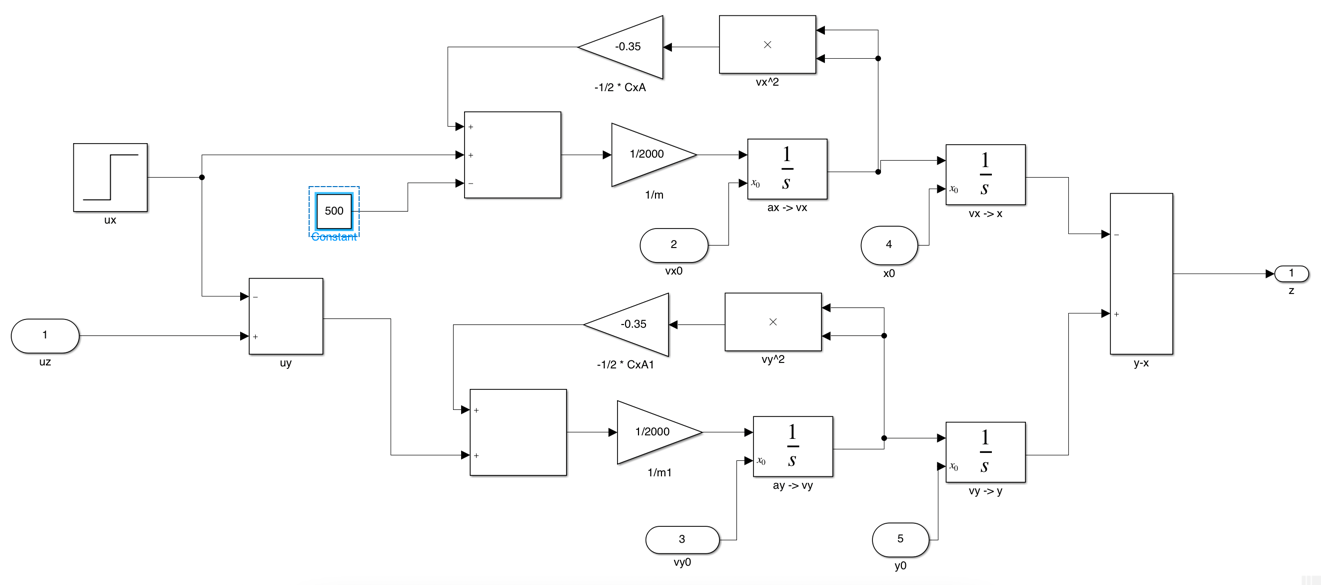

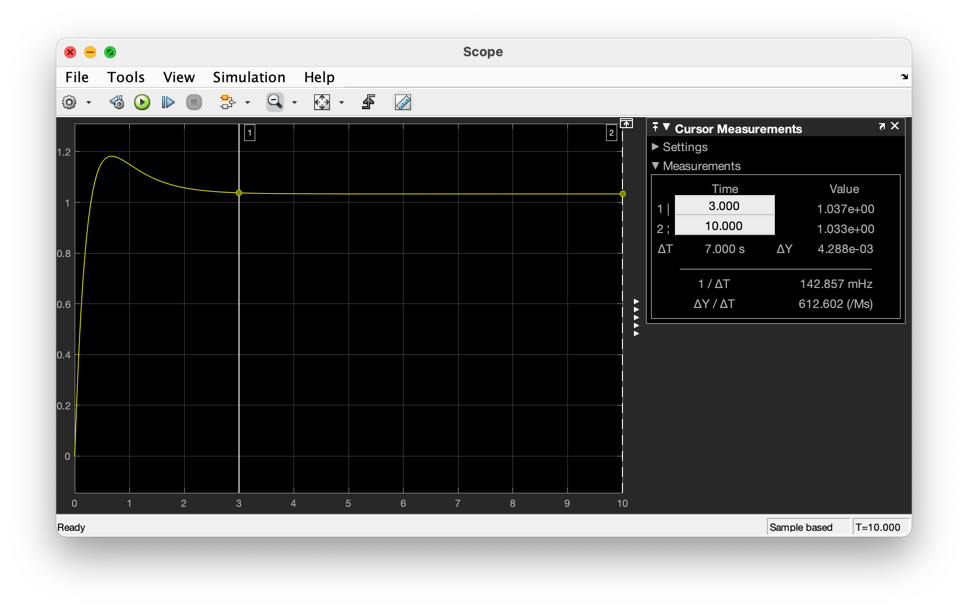

as you can see, there is a steady-state error, as it asymptotically goes to 1.033 instead of 1.00. We try out an integral controller to fix this issue because an integral controller can mitigate steady state error.

When I change the value of $K_i$, the steady-state error decreases, but in turn, overshoot increases. After continuous trial-and-error, I was able to get all the conditions satisfied with a good margin (not borderline satisfaction).

With a $K_p = 35000$, $K_d = 18000$, and $K_i = 8000$, the following scope is plotted.

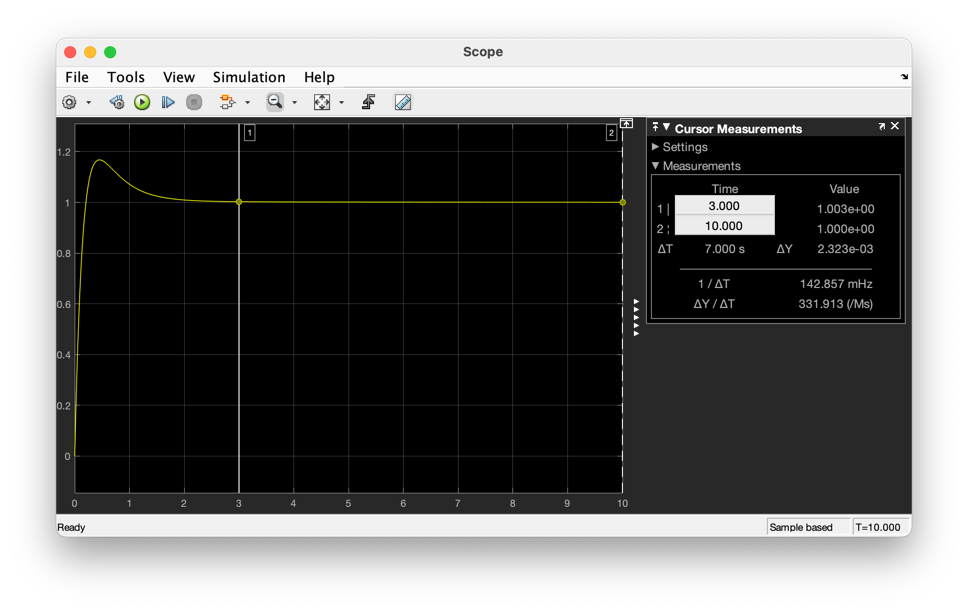

which satisfies all the initial conditions and does it very well. Now, to try it with the new values of $A$ and $C_x$, we end up with the plot:

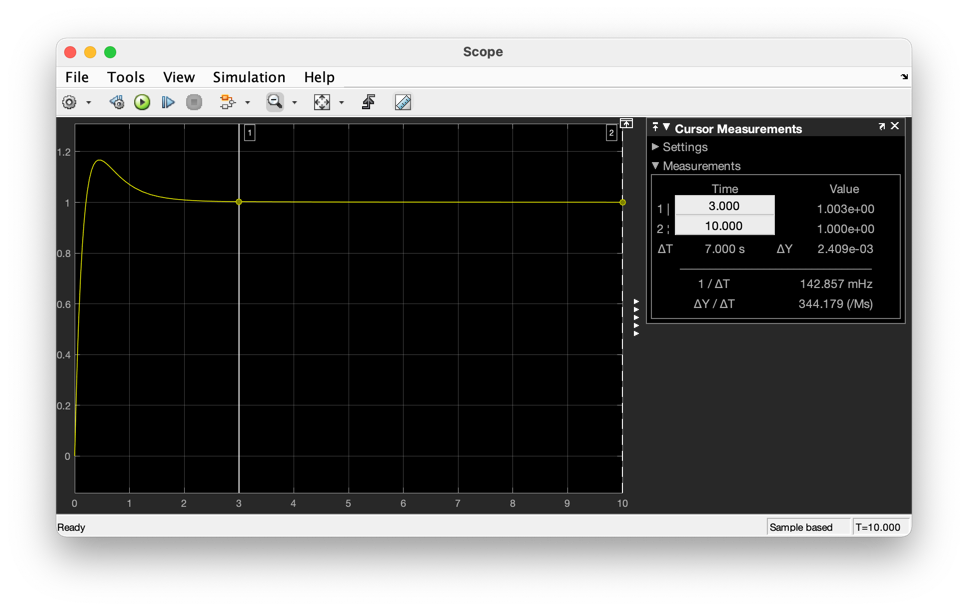

which works! Linearization works very well as a simplication for non-linear systems, especially when you are dealing with events that occur around the equilibrium point (which we defined to be $v_{x_0} = v_{y_0} = 100$). In fact, it worked for quit a significant percentage of the area around those numbers. I remember in one example, when the distances were 5 apart, it worked up to 135!. This was really amazing for me to see and it was cool seeing the ability to linearize nonlinear systems using a differential and then solving it like we did normally. This project really made me undersatnd how PID worked together and let me see in action how everything made everything else change. I especially enjoyed parts 5-7 because I could see the scope plots and how they changed depending on influences like wind.